# Proyecto Imagen 2023

## Input images

addpath('LearningPrototypes\');
selected_path = uigetdir %Choose the directory

selected_path = 'C:\Users\Usuario\Desktop\PROYECTO IMAGEN\LearningPrototypes'

archives = dir(fullfile(selected_path, '*.jpg'));
images={archives.name} % A structure array is a data type that groups related data using data containers

images = 1×27 cell array
    {'F01.jpg'}    {'F02.jpg'}    {'F03.jpg'}    {'F07.jpg'}    {'F08.jpg'}    {'F09.jpg'}    {'F13.jpg'}    {'F14.jpg'}    {'F15.jpg'}    {'F19.jpg'}    {'F20.jpg'}    {'F21.jpg'}    {'F25.jpg'}    {'F26.jpg'}    {'F27.jpg'}    {'F31.jpg'}    {'F32.jpg'}    {'F33.jpg'}    {'F37.jpg'}    {'F38.jpg'}    {'F39.jpg'}    {'F44.jpg'}    {'F45.jpg'}    {'F46.jpg'}    {'F51.jpg'}    {'F52.jpg'}    {'F53.jpg'}


numImages=length(images)% called fields. Each field can contain any type of data. Access data in a field using dot notation of

numImages = 27

% the form structName.fieldName

## Colour improvement

characteristics=[];
for i=1:numImages
    OriginalImage=imread(images{i});
    OriginalImage=im2double(OriginalImage); % DOUBLE
    
    % Coloured Images to B&W images
    R=OriginalImage(:,:,1); % R
    G=OriginalImage(:,:,2); % G
    B=OriginalImage(:,:,3); % B
    BWImage = 0.3*R+0.59*G+0.11*B; %luminance
    
    % Min and Max luminance
    maxLuminance=max(max(BWImage)); %max from columns maxs
    minLuminance=min(min(BWImage));
    BWContrastImage=(BWImage-minLuminance)/(maxLuminance-minLuminance);
    R = ((R - minLuminance) ./ (maxLuminance  - minLuminance));
    G = ((G - minLuminance) ./ (maxLuminance  - minLuminance));
    B = ((B - minLuminance) ./ (maxLuminance  - minLuminance));

    % Convert to RGB images and plotting time
    RGBContrastImage = cat(3, R, G, B);
%     figure;
%     subplot(2,1,1); imshow(OriginalImage); title('Original Image');
%     subplot(2,1,2); imshow(RGBContrastImage); title('Contrast Image');
    
    % Saving changes
    ContrastImages{i}=RGBContrastImage;
    %     imwrite(RGBContrastImage,strcat("FruitImproved"+i+".jpg"));
    
end

## Segmentation + Characteristic Extraction 

%  addpath('ImprovedImages\'); 
%selected_path = uigetdir; archives = dir(fullfile(selected_path, '*.jpg'));
%ContrastImages={archives.name}; numImages=length(ContrastImages);
characteristics=[];
for i=1:numImages
    OriginalImage=ContrastImages{i};
    HSV=rgb2hsv(OriginalImage);
    
    % We need the saturation.
    S = HSV(:,:,2);
    % Conversion from an original image to a binarize one. with a Threshold
    % by Otsu's Method Threshold = multithresh(S); %function that calculates the threshold by Otsu's Method
    BW=imbinarize(S);
    
    % Morphologic Reconstruction Algorithm
    Mask = imfill(BW,'holes'); % rellena huecos de la imagen binaria de entrada BW. En esta sintaxis, un hueco es un conjunto de píxeles de fondo que no se puede alcanzar rellenando el fondo desde el borde de la imagen.
    BinarizeImage=cat(3,OriginalImage(:,:,1).*Mask,OriginalImage(:,:,2).*Mask,OriginalImage(:,:,3).*Mask);
    
    % Plotting time
%         figure;
%         subplot(3,1,1); imshow(OriginalImage); title('Contrast Image');
%         subplot(3,1,2); imshow(Mask,[]); title('Binarization');
%         subplot(3,1,3); imshow(BinarizeImage); title('RGB binarized Image');
%     
    % Saving changes
    %     imwrite(BinarizeImage,strcat("Binarization"+i+".jpg"));
    
    R=BinarizeImage(:,:,1); % R
    G=BinarizeImage(:,:,2); % G
    B=BinarizeImage(:,:,3); % B
    
    %     Need the means of the RGB
    MeanR = mean(nonzeros(R));
    MeanG = mean(nonzeros(G));
    MeanB = mean(nonzeros(B));
    characteristics=[characteristics; MeanR MeanG MeanB];   
    BinarizeImageTot{i}= BW;
end



## Alphabet creation

%Now we need to have a characteristics vector with 3 fruits of each type.
%So we only need to calculate the mean of each one

GoldenApple =(characteristics(1,:)+characteristics(2,:)+characteristics(3,:))./3;
Tangerine = (characteristics(4,:)+characteristics(5,:)+characteristics(6,:))./3;
Strawberry = (characteristics(7,:)+characteristics(8,:)+characteristics(9,:))./3;
Banana = (characteristics(10,:)+characteristics(11,:)+characteristics(12,:))./3;
Pear = (characteristics(13,:)+characteristics(14,:)+characteristics(15,:))./3;
RedApple = (characteristics(16,:)+characteristics(17,:)+characteristics(18,:))./3;
Lemon = (characteristics(19,:)+characteristics(20,:)+characteristics(21,:))./3;
Nectarine = (characteristics(22,:)+characteristics(23,:)+characteristics(24,:))./3;
Loquat = (characteristics(25,:)+characteristics(26,:)+characteristics(27,:))./3;



## Efectivity 

### Basic

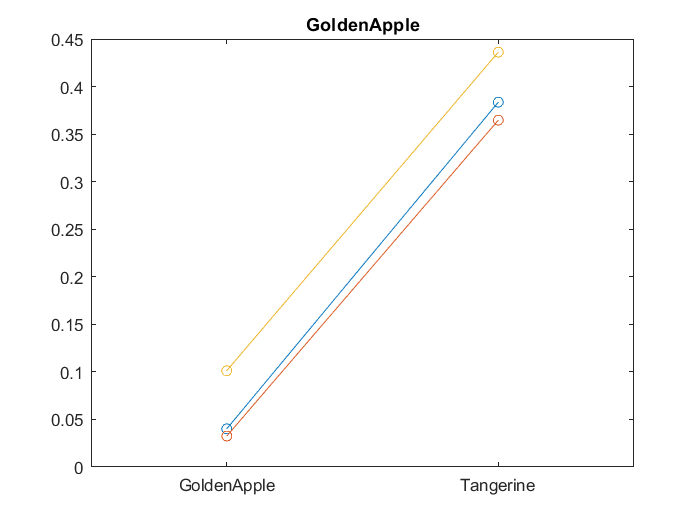

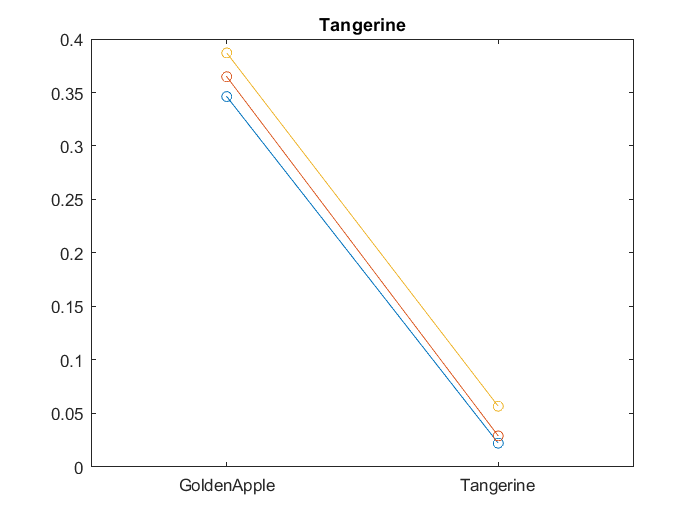

addpath('StudyImagesBasic\');
selected_path = uigetdir;
StudyImages = dir(fullfile(selected_path, '*.jpg'));
Image={StudyImages.name}; numImages=length(Image);
PredictedFruits=[];
Variables = ["GoldenApple", "Tangerine"];
TrueFruits = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine"];
XAxis = categorical(["GoldenApple", "Tangerine"]);
XAxis = reordercats(XAxis,cellstr(XAxis)');

for i=1:numImages
    OriginalImage=imread(Image{i});
    OriginalImage=im2double(OriginalImage); % DOUBLE
    [FruitAvg]=ImageProcessing(OriginalImage);

    %Calculus of the distance from each model fruit values

    DistEuclideanApple = sqrt((GoldenApple(1)-FruitAvg(1))^2+(GoldenApple(2)-FruitAvg(2))^2+(GoldenApple(3)-FruitAvg(3))^2);  %d=√(X1-X2)²+(Y1-Y2)²+(Z1-Z2)²
    DistEuclideanTangerine = sqrt((Tangerine(1)-FruitAvg(1))^2+(Tangerine(2)-FruitAvg(2))^2+(Tangerine(3)-FruitAvg(3))^2);


    %% With the fruits give
    Distances=[DistEuclideanApple DistEuclideanTangerine];
    MinDistance= min (Distances);
    if (MinDistance == DistEuclideanApple)
        Fruit = "GoldenApple";
    elseif (MinDistance == DistEuclideanTangerine)
        Fruit = "Tangerine";
    else
        Fruit = "This fruit is not recognized"
    end
    PredictedFruits=[PredictedFruits Fruit];

     
    if(i~=1)
        if(TrueFruits(i)==TrueFruits(i-1))

            plot(XAxis, Distances, '-o');
            hold on;
        else
            figure;
            plot(XAxis, Distances, '-o');
            title(TrueFruits(i));
            hold on;
        end
    elseif(i==1)
        figure;
        plot(XAxis, Distances, '-o');
        title(TrueFruits(i));
        hold on;

    end
end

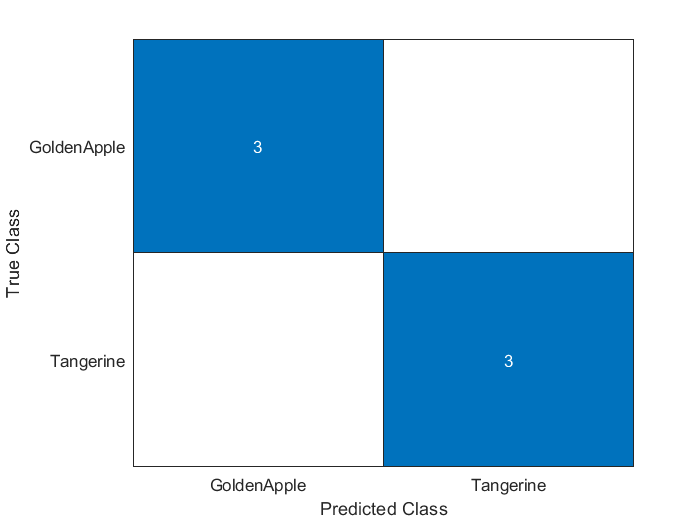


figure;

figure;
C = confusionmat(TrueFruits, PredictedFruits, 'Order', Variables);
confusionchart(C, Variables)

### More images

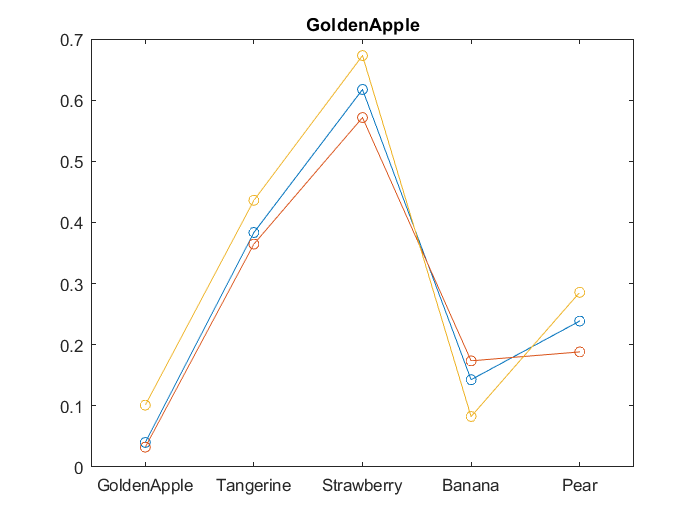

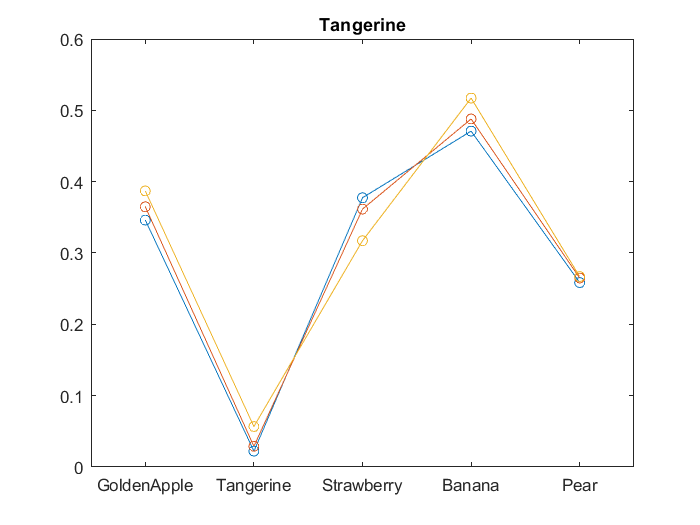

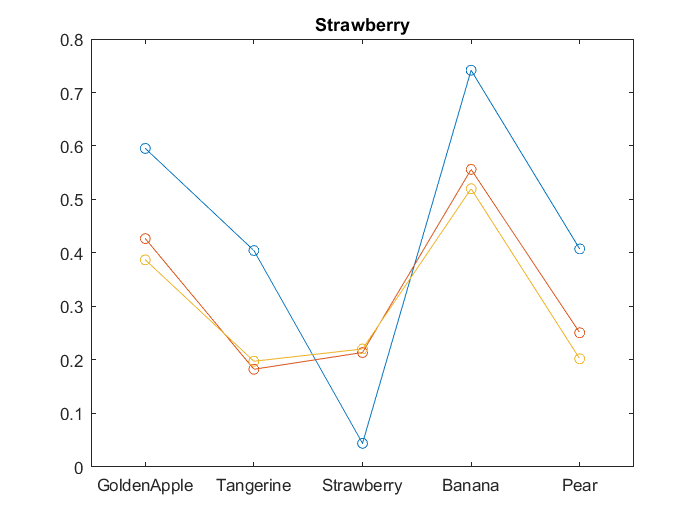

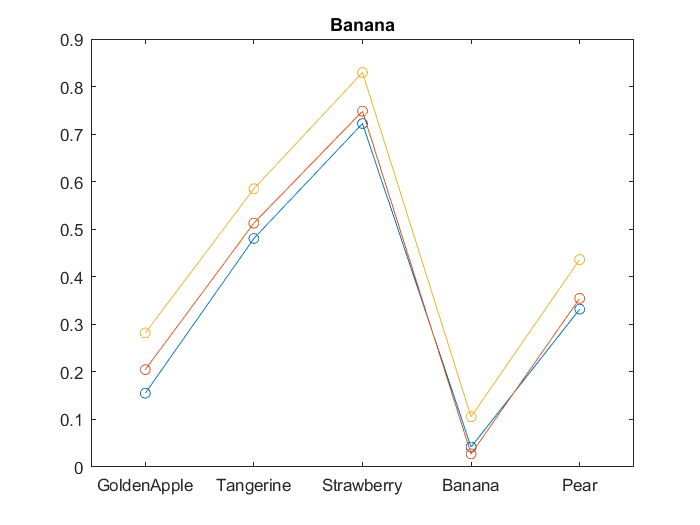

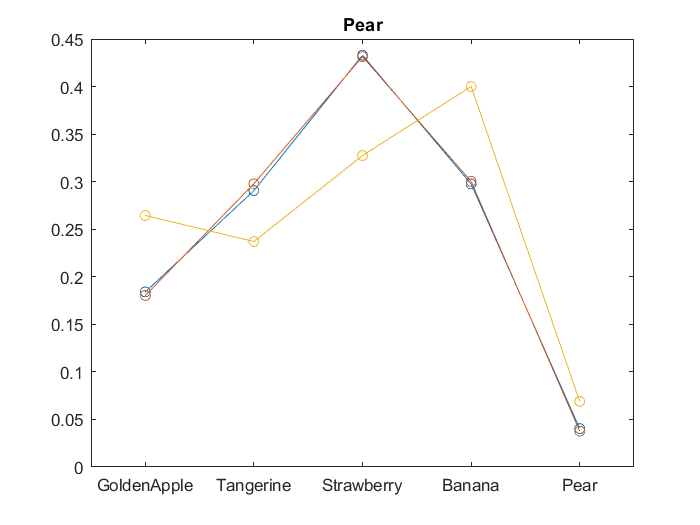

addpath('StudyImages\');
selected_path = uigetdir;
StudyImages = dir(fullfile(selected_path, '*.jpg'));
Image={StudyImages.name}; numImages=length(Image);
PredictedFruits=[];
% % With the fruits given
 Variables = ["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear"];
 TrueFruits = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine",  "Strawberry", "Strawberry", "Strawberry",  "Banana", "Banana", "Banana",    "Pear", "Pear", "Pear"];
XAxis = categorical(["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear"]);
XAxis = reordercats(XAxis,cellstr(XAxis)');
for i=1:numImages
    OriginalImage=imread(Image{i});
    OriginalImage=im2double(OriginalImage); % DOUBLE
    [FruitAvg]=ImageProcessing(OriginalImage);
    
    %Calculus of the distance from each model fruit values
    %d=√(X1-X2)²+(Y1-Y2)²+(Z1-Z2)²

DistEuclideanApple = sqrt((GoldenApple(1)-FruitAvg(1))^2+(GoldenApple(2)-FruitAvg(2))^2+(GoldenApple(3)-FruitAvg(3))^2); 
DistEuclideanTangerine = sqrt((Tangerine(1)-FruitAvg(1))^2+(Tangerine(2)-FruitAvg(2))^2+(Tangerine(3)-FruitAvg(3))^2);
DistEuclideanStrawberry = sqrt((Strawberry(1)-FruitAvg(1))^2+(Strawberry(2)-FruitAvg(2))^2+(Strawberry(3)-FruitAvg(3))^2);
DistEuclideanBanana = sqrt((Banana(1)-FruitAvg(1))^2+(Banana(2)-FruitAvg(2))^2+(Banana(3)-FruitAvg(3))^2);
DistEuclideanPear = sqrt((Pear(1)-FruitAvg(1))^2+(Pear(2)-FruitAvg(2))^2+(Pear(3)-FruitAvg(3))^2);

 
    %% With the fruits given
    % Distances=[DistApple DistTangerine DistStrawberry DistBanana DistPear];
    %With extra fruits
    Distances=[DistEuclideanApple; DistEuclideanTangerine; DistEuclideanStrawberry; DistEuclideanBanana; DistEuclideanPear];


    [MinDistance]= min (Distances);
    
    if (MinDistance == DistEuclideanApple)
        Fruit = "GoldenApple";
    elseif (MinDistance == DistEuclideanTangerine)
        Fruit = "Tangerine";
    elseif (MinDistance == DistEuclideanStrawberry)
        Fruit = "Strawberry";
    elseif (MinDistance == DistEuclideanBanana)
        Fruit = "Banana";
    elseif (MinDistance == DistEuclideanPear)
        Fruit = "Pear";
    else
        Fruit = "This fruit is not recognized"
    end
    
    PredictedFruits=[PredictedFruits Fruit];
    
    if(i~=1)
        if(TrueFruits(i)==TrueFruits(i-1))

            plot(XAxis, Distances, '-o');
            hold on;
        else
            figure;
            plot(XAxis, Distances, '-o');
            title(TrueFruits(i));
            hold on;
        end
    elseif(i==1)
        figure;
        plot(XAxis, Distances, '-o');
        title(TrueFruits(i));
        hold on;

    end
end

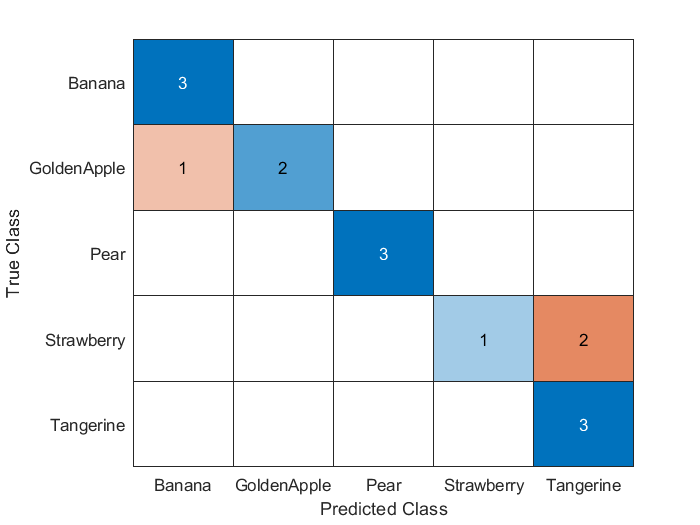


figure;
C = confusionmat(TrueFruits, PredictedFruits, 'Order', Variables);
confusionchart(C, Variables)

### Extra images

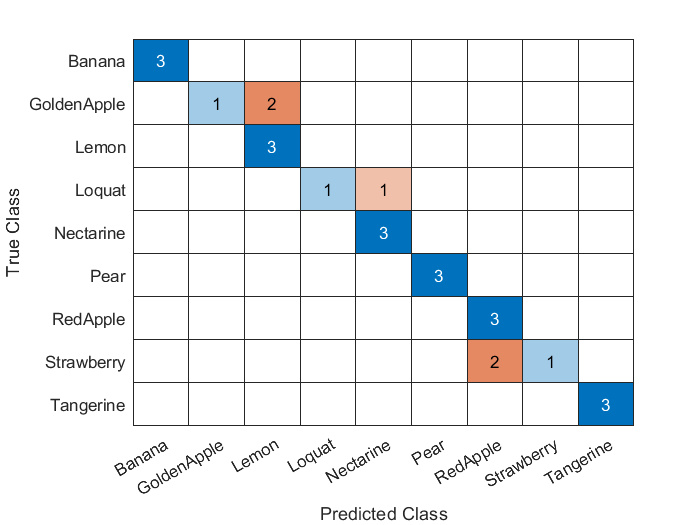

addpath('StudyImages\');
addpath('StudyImagesExtra\');
selected_path = uigetdir;
StudyImages = dir(fullfile(selected_path, '*.jpg'));
Image={StudyImages.name}; numImages=length(Image);
PredictedFruits=[];
FruitsRGB=[];
VectorColourFruits=[];

%With extra fruits
Variables = ["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear", "RedApple", "Lemon", "Nectarine", "Loquat"];
TrueFruits = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine",  "Strawberry", "Strawberry", "Strawberry",  "Banana", "Banana", "Banana",    "Pear", "Pear", "Pear", "RedApple", "RedApple", "RedApple", "Lemon", "Lemon", "Lemon",    "Nectarine", "Nectarine", "Nectarine", "Loquat", "Loquat"];
XAxis = categorical(["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear", "RedApple", "Lemon", "Nectarine", "Loquat"]);
XAxis = reordercats(XAxis,cellstr(XAxis)');

for i=1:numImages
    OriginalImage=imread(Image{i});
    OriginalImage=im2double(OriginalImage); % DOUBLE
    FruitAvg=ImageProcessing(OriginalImage);
    FruitsRGB=[FruitsRGB; FruitAvg];
    %Calculus of the distance from each model fruit values
DistEuclideanApple = sqrt((GoldenApple(1)-FruitAvg(1))^2+(GoldenApple(2)-FruitAvg(2))^2+(GoldenApple(3)-FruitAvg(3))^2); 
DistEuclideanTangerine = sqrt((Tangerine(1)-FruitAvg(1))^2+(Tangerine(2)-FruitAvg(2))^2+(Tangerine(3)-FruitAvg(3))^2);
DistEuclideanStrawberry = sqrt((Strawberry(1)-FruitAvg(1))^2+(Strawberry(2)-FruitAvg(2))^2+(Strawberry(3)-FruitAvg(3))^2);
DistEuclideanBanana = sqrt((Banana(1)-FruitAvg(1))^2+(Banana(2)-FruitAvg(2))^2+(Banana(3)-FruitAvg(3))^2);
DistEuclideanPear = sqrt((Pear(1)-FruitAvg(1))^2+(Pear(2)-FruitAvg(2))^2+(Pear(3)-FruitAvg(3))^2);
DistEuclideanRedApple = sqrt((RedApple(1)-FruitAvg(1))^2+(RedApple(2)-FruitAvg(2))^2+(RedApple(3)-FruitAvg(3))^2);
DistEuclideanLemon = sqrt((Lemon(1)-FruitAvg(1))^2+(Lemon(2)-FruitAvg(2))^2+(Lemon(3)-FruitAvg(3))^2);
DistEuclideanNectarine = sqrt((Nectarine(1)-FruitAvg(1))^2+(Nectarine(2)-FruitAvg(2))^2+(Nectarine(3)-FruitAvg(3))^2);
DistEuclideanLoquat = sqrt((Loquat(1)-FruitAvg(1))^2+(Loquat(2)-FruitAvg(2))^2+(Loquat(3)-FruitAvg(3))^2);

    %% With the fruits given
    % Distances=[DistApple DistTangerine DistStrawberry DistBanana DistPear];
    %With extra fruits
    Distances=[DistEuclideanApple; DistEuclideanTangerine; DistEuclideanStrawberry; DistEuclideanBanana; DistEuclideanPear; DistEuclideanRedApple; DistEuclideanLemon; DistEuclideanNectarine; DistEuclideanLoquat];

    [MinDistance]= min (Distances);
    
    if (MinDistance == DistEuclideanApple)
        Fruit = "GoldenApple";
    elseif (MinDistance == DistEuclideanTangerine)
        Fruit = "Tangerine";
    elseif (MinDistance == DistEuclideanStrawberry)
        Fruit = "Strawberry";
    elseif (MinDistance == DistEuclideanBanana)
        Fruit = "Banana";
    elseif (MinDistance == DistEuclideanPear)
        Fruit = "Pear";
    elseif (MinDistance == DistEuclideanRedApple)
        Fruit = "RedApple";
    elseif (MinDistance == DistEuclideanLemon)
        Fruit = "Lemon";
    elseif (MinDistance == DistEuclideanNectarine)
        Fruit = "Nectarine";
    elseif (MinDistance == DistEuclideanLoquat)
        Fruit = "Loquat";
    else
        Fruit = "This fruit is not recognized"
    end
    
    PredictedFruits=[PredictedFruits Fruit];
    
     
%     if(i~=1)
%         if(TrueFruits(i)==TrueFruits(i-1))
% 
%             plot(XAxis, Distances, '-o');
%             hold on;
%         else
%             figure;
%             plot(XAxis, Distances, '-o');
%             title(TrueFruits(i));
%             hold on;
%         end
%     elseif(i==1)
%         figure;
%         plot(XAxis, Distances, '-o');
%         title(TrueFruits(i));
%         hold on;
% 
%     end
end

figure;

C = confusionmat(TrueFruits, PredictedFruits, 'Order', Variables);
confusionchart(C, Variables);

save('FruitColours','FruitsRGB')

## Searching the solution to the classification problems

Now we need to detect the way the  RGB values are distributed on space for the problematic pair of fruits: Lemon(22,23,24)- - Golden Apple(1,2,3), Nectarine(19,20,21) - Loquat, Red Apple (16,17,18)- Strawberry(7,8,9). And if we watch aboutt 

load('FruitColours.mat','FruitsRGB');
TrueFruits = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine",  "Strawberry", "Strawberry", "Strawberry",  "Banana", "Banana", "Banana", "Pear", "Pear", "Pear", "RedApple", "RedApple", "RedApple", "Lemon", "Lemon", "Lemon", "Nectarine", "Nectarine", "Nectarine","Loquat", "Loquat"];
FruitsRGB

FruitsRGB =     0.7295    0.6102    0.1526
    0.6795    0.5872    0.1634
    0.7570    0.6525    0.1914
    0.7161    0.2481    0.0878
    0.7057    0.2278    0.0971
    0.6658    0.2076    0.0894
    0.3191    0.1350    0.0787
    0.5514    0.1896    0.1460
    0.5302    0.2417    0.1501
    0.7867    0.6858    0.2217



%Problems
LemonGoldenAppleRGB=[FruitsRGB(1,:); FruitsRGB(2,:); FruitsRGB(3,:); FruitsRGB(19,:); FruitsRGB(20,:); FruitsRGB(21,:)];
LoquatNectarineRGB=[FruitsRGB(22,:); FruitsRGB(23,:); FruitsRGB(24,:); FruitsRGB(26,:); FruitsRGB(25,:)];
StrawberryRedAppleRGB=[FruitsRGB(7,:); FruitsRGB(8,:); FruitsRGB(9,:); FruitsRGB(16,:); FruitsRGB(17,:); FruitsRGB(18,:)];

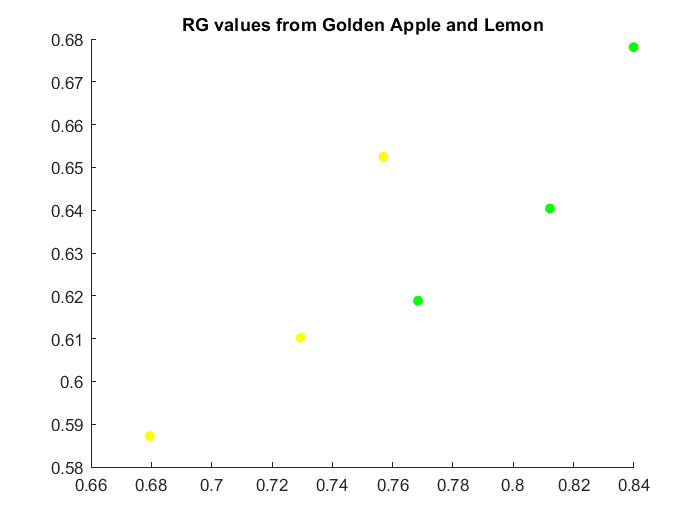

%Problen with Lemon - Golden Apple
LemonGoldenAppleR=[LemonGoldenAppleRGB(:,1)];
LemonGoldenAppleG=[LemonGoldenAppleRGB(:,2)];  
LemonGoldenAppleB=[LemonGoldenAppleRGB(:,3)]; 

figure;
scatter(LemonGoldenAppleR(1:3,:),LemonGoldenAppleG(1:3,:),'filled','o','y');
title("RG values from Golden Apple and Lemon");
hold on;
scatter(LemonGoldenAppleR(4:6,:),LemonGoldenAppleG(4:6,:),'filled','o','g');

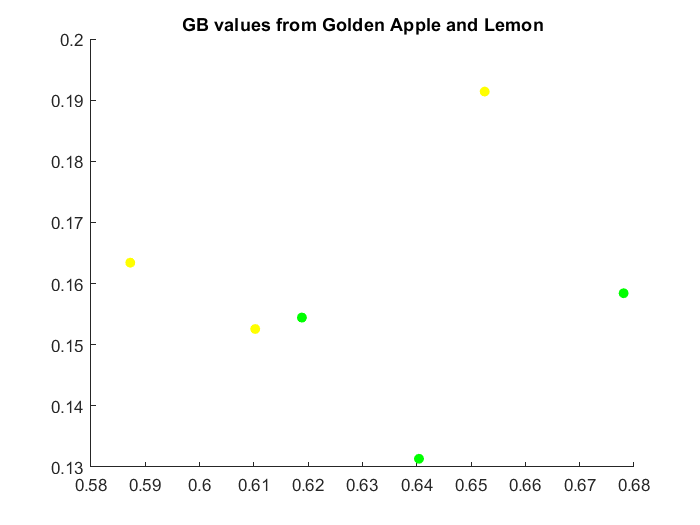

x1=0.387142857142857;
y1=0.107619047619048;
x2=0.728571428571429;
y2=0.922857142857143;
mRGGoldenAppleLemon = (y2-y1)/(x2-x1);

figure;
scatter(LemonGoldenAppleG(1:3,:),LemonGoldenAppleB(1:3,:),'filled','o','y');
title("GB values from Golden Apple and Lemon");
hold on;
scatter(LemonGoldenAppleG(4:6,:),LemonGoldenAppleB(4:6,:),'filled','o','g');
title("GB values from Golden Apple and Lemon");

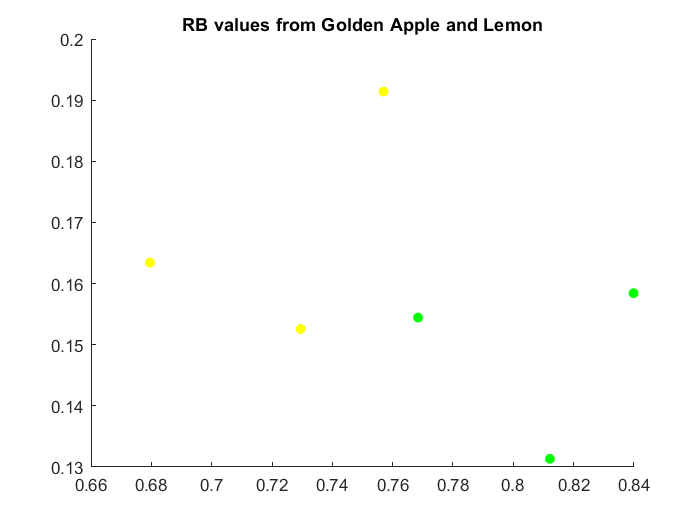


figure;
scatter(LemonGoldenAppleR(1:3,:),LemonGoldenAppleB(1:3,:),'filled','o','y');
title("RB values from Golden Apple and Lemon");
hold on;
scatter(LemonGoldenAppleR(4:6,:),LemonGoldenAppleB(4:6,:),'filled','o','g');
title("RB values from Golden Apple and Lemon");

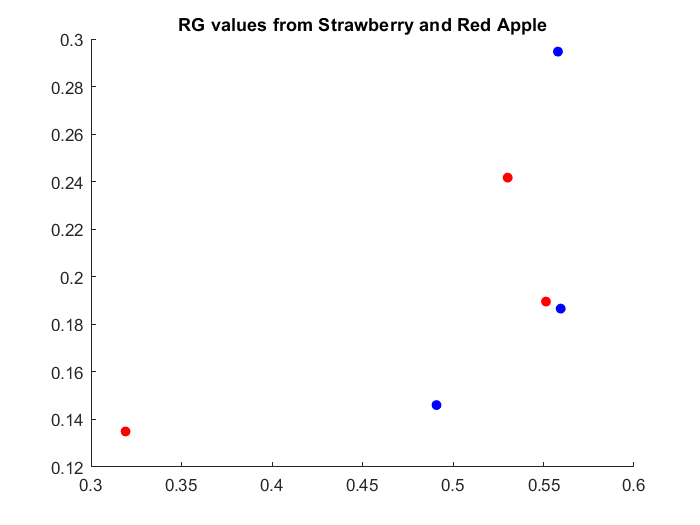


x1=0.474285714285714;
y1=0.110428571428571;
x2=0.177142857142857;
y2=0.751476190476191;
mRBGoldenAppleLemon = (y2-y1)/(x2-x1);


%Problen with Strawberry - RedApple
StrawberryRedAppleR=[StrawberryRedAppleRGB(:,1)];
StrawberryRedAppleG=[StrawberryRedAppleRGB(:,2)];  
StrawberryRedAppleB=[StrawberryRedAppleRGB(:,3)]; 

figure;
scatter(StrawberryRedAppleR(1:3,:),StrawberryRedAppleG(1:3,:),'filled','o','r');
title("RG values from Strawberry and Red Apple");
hold on;
scatter(StrawberryRedAppleR(4:6,:),StrawberryRedAppleG(4:6,:),'filled','o','b');
title("RG values from Strawberry and Red Apple");

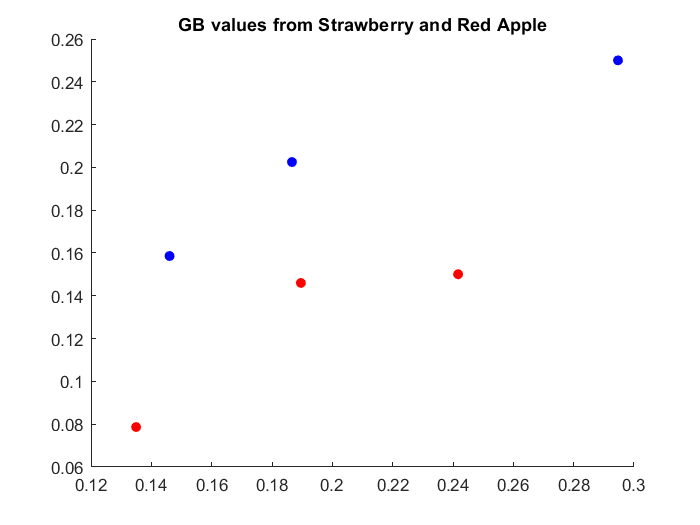


figure;
scatter(StrawberryRedAppleG(1:3,:),StrawberryRedAppleB(1:3,:),'filled','o','r');
title("GB values from Strawberry and Red Apple");
hold on;
scatter(StrawberryRedAppleG(4:6,:),StrawberryRedAppleB(4:6,:),'filled','o','b');
title("GB values from Strawberry and Red Apple");

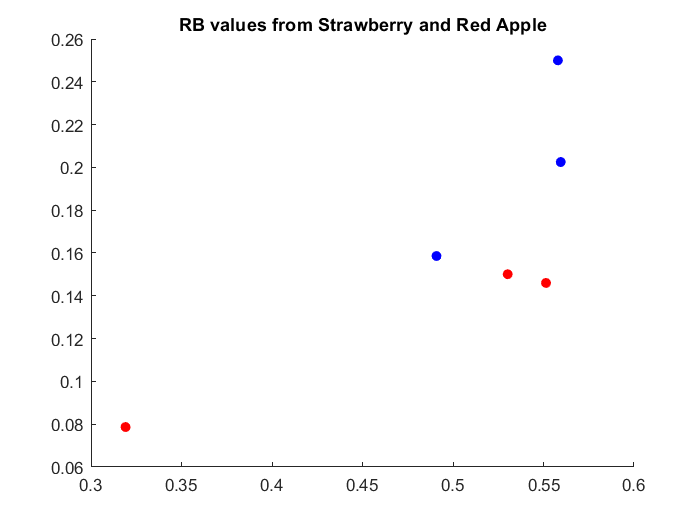

x1=0.135714285714286;
y1=0.367571428571429;
x2=0.782857142857143;
y2=0.412428571428572;
mGBStrawberryRedApple = (y2-y1)/(x2-x1);


figure;
scatter(StrawberryRedAppleR(1:3,:),StrawberryRedAppleB(1:3,:),'filled','o','r');
title("RB values from Strawberry and Red Apple");
hold on;
scatter(StrawberryRedAppleR(4:6,:),StrawberryRedAppleB(4:6,:),'filled','o','b');
title("RB values from Strawberry and Red Apple");

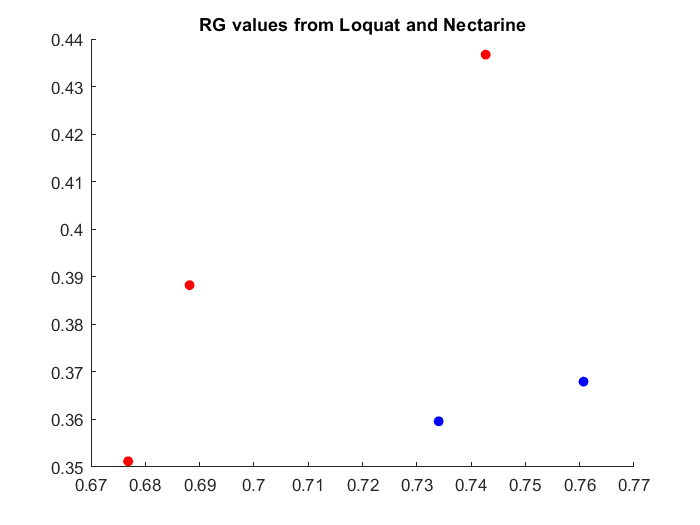

x1=0.132857142857143;
y1=0.213285714285714;
x2=0.747142857142857;
y2=0.406714285714286;
mRBStrawberryRedApple = (y2-y1)/(x2-x1);




%Problen with Loquat - Nectarine
LoquatNectarineR=[LoquatNectarineRGB(:,1)];
LoquatNectarineG=[LoquatNectarineRGB(:,2)];  
LoquatNectarineB=[LoquatNectarineRGB(:,3)]; 

figure;
scatter(LoquatNectarineR(1:3,:),LoquatNectarineG(1:3,:),'filled','o','r');
title("RG values from Loquat and Nectarine");
hold on;
scatter(LoquatNectarineR(4:5,:),LoquatNectarineG(4:5,:),'filled','o','b');
title("RG values from Loquat and Nectarine");

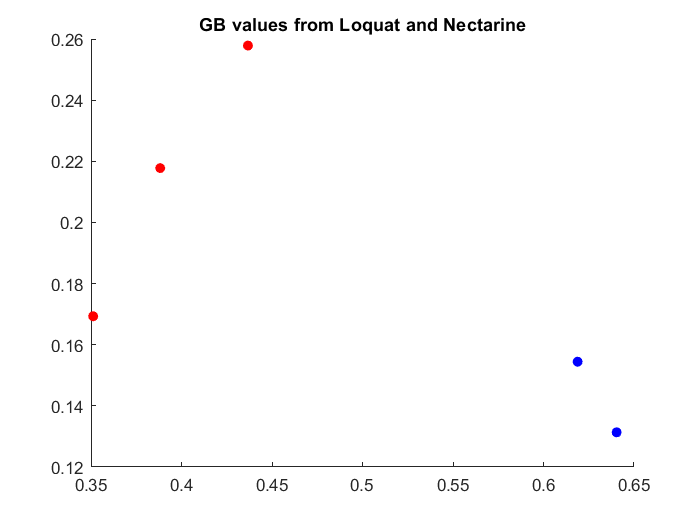

x1=0.364285714285714;
y1=0.112333333333333;
x2=0.508571428571429;
y2=0.528619047619048;
mRBLoquatNectarine = (y2-y1)/(x2-x1);
figure;
scatter(LoquatNectarineG(1:3,:),LoquatNectarineB(1:3,:),'filled','o','r');
title("GB values from Loquat and Nectarine");
hold on;
scatter(LemonGoldenAppleG(4:5,:),LemonGoldenAppleB(4:5,:),'filled','o','b');
title("GB values from Loquat and Nectarine");

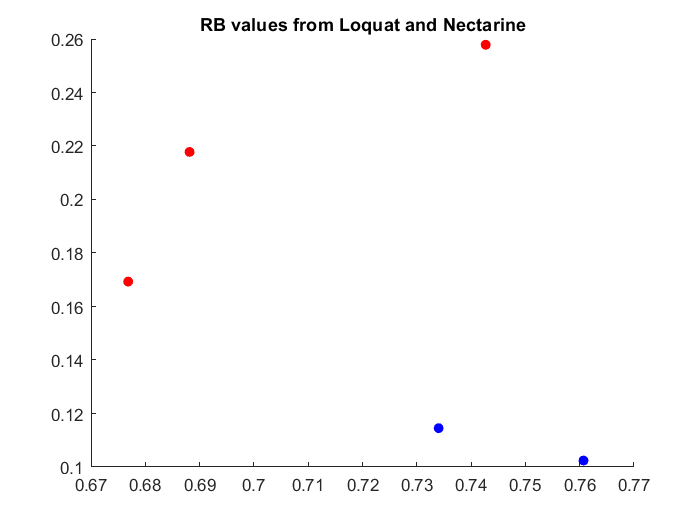

x1=0.813152400835073; %0.813152400835073,0.129436325678497
y1=0.828694323144105; %0.828694323144105,0.10589519650655
x2=0.129436325678497;
y2=0.10589519650655;
mGBLoquatNectarine = (y2-y1)/(x2-x1);
figure;
scatter(LoquatNectarineR(1:3,:),LoquatNectarineB(1:3,:),'filled','o','r');
title("RB values from Loquat and Nectarine");
hold on;
scatter(LoquatNectarineR(4:5,:),LoquatNectarineB(4:5,:),'filled','o','b');
title("RB values from Loquat and Nectarine");

x1=0.131428571428571;
y1=0.10852380952381;
x2=0.725714285714286;
y2=0.740047619047619;
mRBLoquatNectarine = (y2-y1)/(x2-x1);



## Doing some things with other image properties

### Area

areatot=[];
areacomp=[];
for i = 1:numImages
    % Etiquetar la imagen
    maskbw = bwlabel(BinarizeImageTot{i});
    total=bwarea(maskbw);
    areacomp=[areacomp total];
end
areatot= [TrueFruits; areacomp]

areatot = 2×26 string array
    "GoldenApple"    "GoldenApple"    "GoldenApple"    "Tangerine"     "Tangerine"     "Tangerine"    "Strawberry"    "Strawberry"    "Strawberry"    "Banana"        "Banana"         "Banana"         "Pear"           "Pear"         "Pear"           "RedApple"      "RedApple"     "RedApple"       "Lemon"        "Lemon"         "Lemon"          "Nectarine"    "Nectarine"     "Nectarine"      "Loquat"        "Loquat"    
    "1363824.375"    "1552722.75"     "1411689"        "1125077.75"    "931384.125"    "897468"       "477889.75"     "556925.125"    "497162.5"      "2025003.25"    "1753879.625"    "1566526.375"    "2158744.625"    "2140122.5"    "1940045.125"    "1853893.75"    "1806026.5"    "1314199.125"    "1202108.5"    "1344002.75"    "2337629.125"    "1274846.5"    "783781.125"    "1342104.375"    "686084.125"    "610904.625"


### Radii

addpath('StudyImagesExtra\');
selected_path = uigetdir;
StudyImages = dir(fullfile(selected_path, '*.jpg'));
Image={StudyImages.name}; 
numImages=length(Image);
areacomp=[];

TrueFruitsExtra = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine",  "Strawberry", "Strawberry", "Strawberry",  "Banana", "Banana", "Banana",    "Pear", "Pear", "Pear", "RedApple", "RedApple", "RedApple", "Lemon", "Lemon", "Lemon",    "Nectarine", "Nectarine", "Nectarine", "Loquat", "Loquat"];

clear radiitot;

for i=1:numImages
 OriginalImage=imread(Image{i});
 OriginalImage=im2double(OriginalImage); % DOUBLE
 bw = Binarization(OriginalImage);

stats = regionprops("table",bw,"Centroid", "MajorAxisLength","MinorAxisLength");
centers = stats.Centroid;
numCenters(i)=length(centers);
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
radii=mean(radii);
radiitot(i)=radii;

 maskbw = bwlabel(Mask);
 total=bwarea(maskbw);
 areacomp=[areacomp total];
    
end
numcenterscomp=[numCenters];
numcenterstot=[TrueFruitsExtra; numCenters]

numcenterstot = 2×26 string array
    "GoldenApple"    "GoldenApple"    "GoldenApple"    "Tangerine"    "Tangerine"    "Tangerine"    "Strawberry"    "Strawberry"    "Strawberry"    "Banana"    "Banana"    "Banana"    "Pear"    "Pear"    "Pear"    "RedApple"    "RedApple"    "RedApple"    "Lemon"    "Lemon"    "Lemon"    "Nectarine"    "Nectarine"    "Nectarine"    "Loquat"    "Loquat"
    "34"             "61"             "7"              "64"           "9"            "106"          "223"           "246"           "121"           "97"        "113"       "49"        "146"     "90"      "83"      "40"          "247"         "203"         "14"       "8"        "5"        "35"           "29"           "42"           "184"       "29"    


radiicomp=[radiitot]

radiicomp =    25.7986   13.7513  108.7551   10.0161   68.5123    6.4959    3.5345    3.1984    4.9299    9.8369   10.4970   21.6153    7.5183   12.1448   13.0632   20.5317    4.5551    4.7889   72.4213   83.8107  158.3981   22.2049   23.2881   13.1671    4.8026   16.5495


radiitot= [TrueFruitsExtra; radiitot]

radiitot = 2×26 string array
    "GoldenApple"    "GoldenApple"    "GoldenApple"    "Tangerine"    "Tangerine"    "Tangerine"    "Strawberry"    "Strawberry"    "Strawberry"    "Banana"      "Banana"      "Banana"      "Pear"        "Pear"        "Pear"        "RedApple"    "RedApple"    "RedApple"    "Lemon"       "Lemon"       "Lemon"       "Nectarine"    "Nectarine"    "Nectarine"    "Loquat"      "Loquat"  
    "25.7986"        "13.75133"       "108.7551"       "10.01609"     "68.51226"     "6.495926"     "3.534519"      "3.198399"      "4.929868"      "9.836904"    "10.49696"    "21.61531"    "7.518299"    "12.14477"    "13.06318"    "20.5317"     "4.555105"    "4.788908"    "72.42131"    "83.81071"    "158.3981"    "22.20488"     "23.28809"     "13.16711"     "4.802641"    "16.54948"


areatot= [TrueFruitsExtra; areacomp]

areatot = 2×26 string array
    "GoldenApple"    "GoldenApple"    "GoldenApple"    "Tangerine"      "Tangerine"      "Tangerine"      "Strawberry"     "Strawberry"     "Strawberry"     "Banana"         "Banana"         "Banana"         "Pear"           "Pear"           "Pear"           "RedApple"       "RedApple"       "RedApple"       "Lemon"          "Lemon"          "Lemon"          "Nectarine"      "Nectarine"      "Nectarine"      "Loquat"         "Loquat"     
    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"    "1897816.875"


## Solution with radii

### Efectivity (Extra images)

addpath('StudyImagesExtra\');
selected_path = uigetdir;
StudyImages = dir(fullfile(selected_path, '*.jpg'));
Image={StudyImages.name}; 
numImages=length(Image);
PredictedFruits=[];
FruitsRGB=[];
VectorColourFruits=[];

%With extra fruits
Variables = ["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear", "RedApple", "Lemon", "Nectarine", "Loquat"];
TrueFruits = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine",  "Strawberry", "Strawberry", "Strawberry",  "Banana", "Banana", "Banana",    "Pear", "Pear", "Pear", "RedApple", "RedApple", "RedApple", "Lemon", "Lemon", "Lemon",    "Nectarine", "Nectarine", "Nectarine", "Loquat", "Loquat"];
XAxis = categorical(["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear", "RedApple", "Lemon", "Nectarine", "Loquat"]);
XAxis = reordercats(XAxis,cellstr(XAxis)');

for i=1:numImages
    OriginalImage=imread(Image{i});
    OriginalImage=im2double(OriginalImage); % DOUBLE
    FruitAvg=ImageProcessing(OriginalImage);
    FruitsRGB=[FruitsRGB; FruitAvg];
    %Calculus of the distance from each model fruit values
DistEuclideanApple = sqrt((GoldenApple(1)-FruitAvg(1))^2+(GoldenApple(2)-FruitAvg(2))^2+(GoldenApple(3)-FruitAvg(3))^2); 
DistEuclideanTangerine = sqrt((Tangerine(1)-FruitAvg(1))^2+(Tangerine(2)-FruitAvg(2))^2+(Tangerine(3)-FruitAvg(3))^2);
DistEuclideanStrawberry = sqrt((Strawberry(1)-FruitAvg(1))^2+(Strawberry(2)-FruitAvg(2))^2+(Strawberry(3)-FruitAvg(3))^2);
DistEuclideanBanana = sqrt((Banana(1)-FruitAvg(1))^2+(Banana(2)-FruitAvg(2))^2+(Banana(3)-FruitAvg(3))^2);
DistEuclideanPear = sqrt((Pear(1)-FruitAvg(1))^2+(Pear(2)-FruitAvg(2))^2+(Pear(3)-FruitAvg(3))^2);
DistEuclideanRedApple = sqrt((RedApple(1)-FruitAvg(1))^2+(RedApple(2)-FruitAvg(2))^2+(RedApple(3)-FruitAvg(3))^2);
DistEuclideanLemon = sqrt((Lemon(1)-FruitAvg(1))^2+(Lemon(2)-FruitAvg(2))^2+(Lemon(3)-FruitAvg(3))^2);
DistEuclideanNectarine = sqrt((Nectarine(1)-FruitAvg(1))^2+(Nectarine(2)-FruitAvg(2))^2+(Nectarine(3)-FruitAvg(3))^2);
DistEuclideanLoquat = sqrt((Loquat(1)-FruitAvg(1))^2+(Loquat(2)-FruitAvg(2))^2+(Loquat(3)-FruitAvg(3))^2);

    %% With the fruits given
    % Distances=[DistApple DistTangerine DistStrawberry DistBanana DistPear];
    %With extra fruits
    Distances=[DistEuclideanApple; DistEuclideanTangerine; DistEuclideanStrawberry; DistEuclideanBanana; DistEuclideanPear; DistEuclideanRedApple; DistEuclideanLemon; DistEuclideanNectarine; DistEuclideanLoquat];

    [MinDistance]= min (Distances);
    
    if (MinDistance == DistEuclideanApple)
        Fruit = "GoldenApple";
    elseif (MinDistance == DistEuclideanTangerine)
        Fruit = "Tangerine";
    elseif (MinDistance == DistEuclideanStrawberry||MinDistance == DistEuclideanRedApple)
        if(radiicomp(i)<5)
        Fruit = "Strawberry";
        else
         Fruit = "RedApple";
        end
    elseif (MinDistance == DistEuclideanBanana)
        Fruit = "Banana";
    elseif (MinDistance == DistEuclideanPear)
        Fruit = "Pear";
%     elseif (MinDistance == DistEuclideanRedApple)
%         Fruit = "RedApple";
    elseif (MinDistance == DistEuclideanLemon)
        Fruit = "Lemon";
    elseif (MinDistance == DistEuclideanNectarine||MinDistance == DistEuclideanLoquat)
          if(radiicomp(i)<18.5)
         Fruit = "Loquat";
          else
       Fruit = "Nectarine";
          end
%     elseif (MinDistance == DistEuclideanLoquat)
%         Fruit = "Loquat";
    else
        Fruit = "This fruit is not recognized"
    end
    
    PredictedFruits=[PredictedFruits Fruit];
    
     
%     if(i~=1)
%         if(TrueFruits(i)==TrueFruits(i-1))
% 
%             plot(XAxis, Distances, '-o');
%             hold on;
%         else
%             figure;
%             plot(XAxis, Distances, '-o');
%             title(TrueFruits(i));
%             hold on;
%         end
%     elseif(i==1)
%         figure;
%         plot(XAxis, Distances, '-o');
%         title(TrueFruits(i));
%         hold on;
% 
%     end
end

Unrecognized function or variable 'GoldenApple'.


figure;

C = confusionmat(TrueFruits, PredictedFruits, 'Order', Variables);
confusionchart(C, Variables);

### Efectivity (More images) 

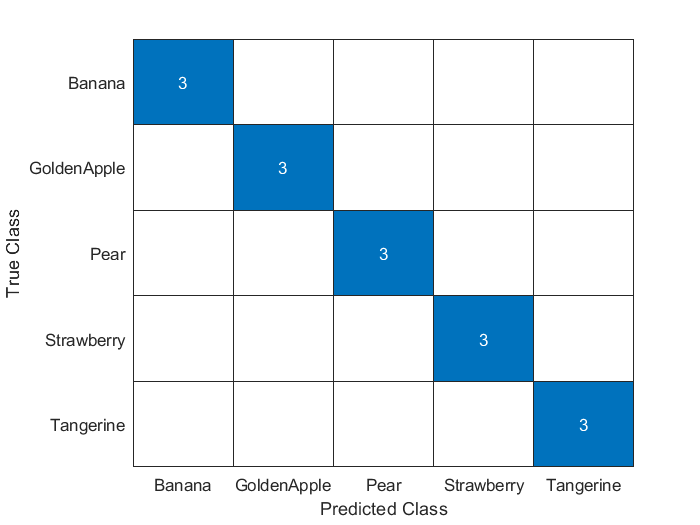

addpath('StudyImages\');
selected_path = uigetdir;
StudyImages = dir(fullfile(selected_path, '*.jpg'));
Image={StudyImages.name}; numImages=length(Image);
PredictedFruits=[];
% % With the fruits given
Variables = ["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear"];
TrueFruits = ["GoldenApple", "GoldenApple", "GoldenApple", "Tangerine", "Tangerine", "Tangerine",  "Strawberry", "Strawberry", "Strawberry",  "Banana", "Banana", "Banana",    "Pear", "Pear", "Pear"];
XAxis = categorical(["GoldenApple", "Tangerine", "Strawberry","Banana", "Pear"]);
XAxis = reordercats(XAxis,cellstr(XAxis)');
for i=1:numImages
    OriginalImage=imread(Image{i});
    OriginalImage=im2double(OriginalImage); % DOUBLE
    [FruitAvg]=ImageProcessing(OriginalImage);
    
    %Calculus of the distance from each model fruit values
    %d=√(X1-X2)²+(Y1-Y2)²+(Z1-Z2)²
    
    DistEuclideanApple = sqrt((GoldenApple(1)-FruitAvg(1))^2+(GoldenApple(2)-FruitAvg(2))^2+(GoldenApple(3)-FruitAvg(3))^2);
    DistEuclideanTangerine = sqrt((Tangerine(1)-FruitAvg(1))^2+(Tangerine(2)-FruitAvg(2))^2+(Tangerine(3)-FruitAvg(3))^2);
    DistEuclideanStrawberry = sqrt((Strawberry(1)-FruitAvg(1))^2+(Strawberry(2)-FruitAvg(2))^2+(Strawberry(3)-FruitAvg(3))^2);
    DistEuclideanBanana = sqrt((Banana(1)-FruitAvg(1))^2+(Banana(2)-FruitAvg(2))^2+(Banana(3)-FruitAvg(3))^2);
    DistEuclideanPear = sqrt((Pear(1)-FruitAvg(1))^2+(Pear(2)-FruitAvg(2))^2+(Pear(3)-FruitAvg(3))^2);
    
    
    %% With the fruits given
    % Distances=[DistApple DistTangerine DistStrawberry DistBanana DistPear];
    %With extra fruits
    Distances=[DistEuclideanApple; DistEuclideanTangerine; DistEuclideanStrawberry; DistEuclideanBanana; DistEuclideanPear];
    
    
    [MinDistance]= min (Distances);
    
    if (MinDistance == DistEuclideanApple||MinDistance == DistEuclideanBanana)
        if numcenterscomp(i)>70
            Fruit = "Banana";
        else
           Fruit = "GoldenApple";
        end
    elseif (MinDistance == DistEuclideanStrawberry||MinDistance == DistEuclideanTangerine)
        if(radiicomp(i)<5)
            Fruit = "Strawberry";
        else
            Fruit = "Tangerine";
        end
    elseif (MinDistance == DistEuclideanPear)
        Fruit = "Pear";
    else
        Fruit = "This fruit is not recognized"
    end
    
    PredictedFruits=[PredictedFruits Fruit];
    
    
end

    figure;
    C = confusionmat(TrueFruits, PredictedFruits, 'Order', Variables);
    confusionchart(C, Variables)